# Практическое задание 1.

Сформировать изображение наименьшего веса в битах (значение указать) с количеством градаций яркости без проявления ложных контуров. DPI изображения не хуже 20. 

Изначально DPI картинок 96.

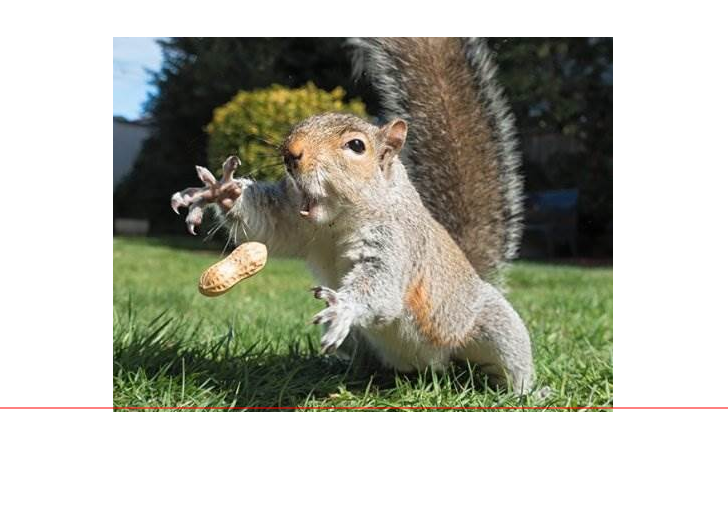

clc
clear
Image=imread('Белка.jpg'); 
imshow(Image);
Line =annotation("line",[0.0 1],[0.2 0.2],'Units','inches','Color','r');

LineSizeInches =Line.Position;

Размер картинки в дюймах

disp(LineSizeInches(3));

    5.0556



DPI данного изображения равно

disp(ceil(500/LineSizeInches(3)-1));

    98



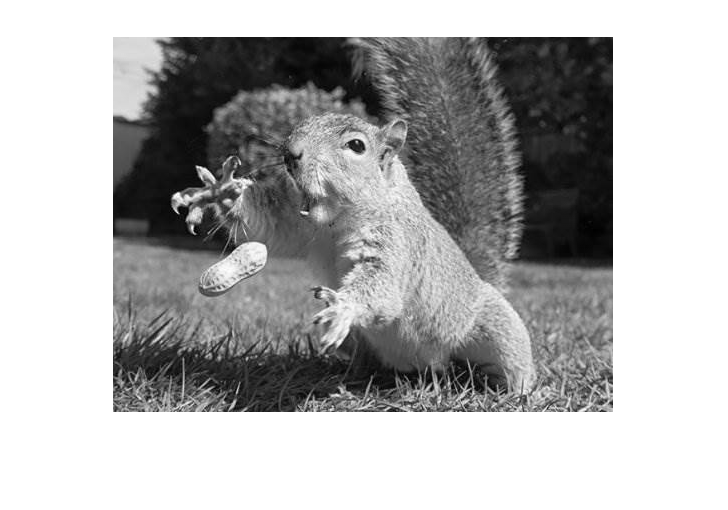

NTSCImage =rgb2ntsc(Image);
GrayImage =NTSCImage(:,:,1);
imshow(GrayImage);

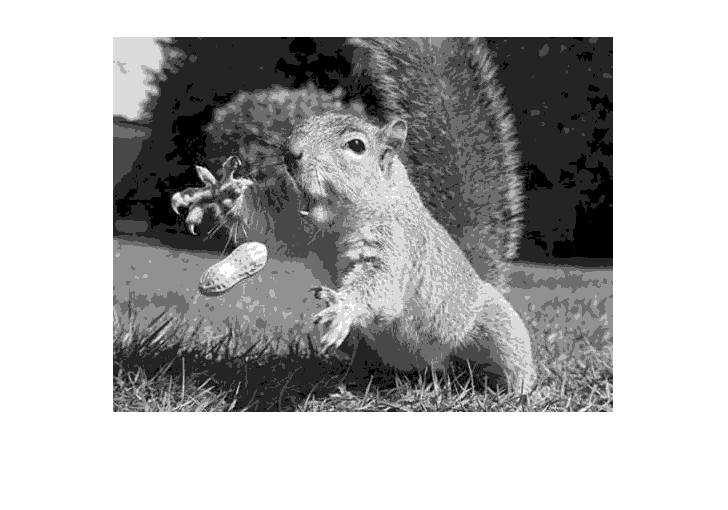

[NewImageGrad,map] = gray2ind(GrayImage,8);
imshow(NewImageGrad,map);

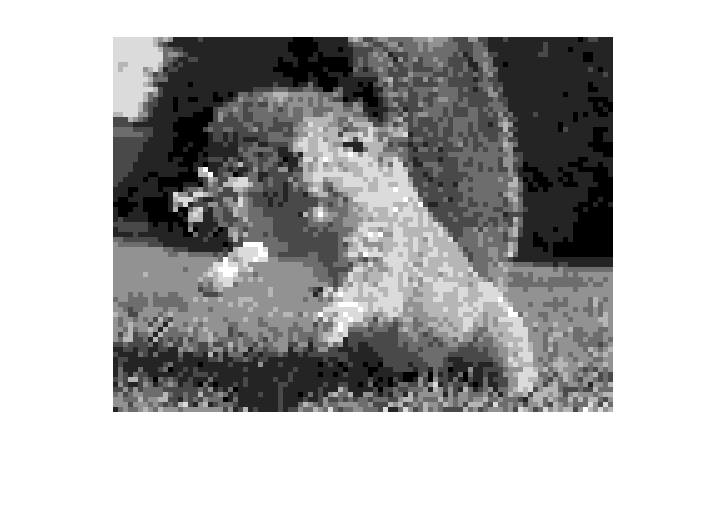

NewSizeImage = imresize(NewImageGrad,0.2,'nearest');
imshow(NewSizeImage,'DisplayRange',[0 7],'InitialMagnification',100/0.2);

Оцените DPI полученного изображения изображения?

Сколько бит информации весит данное изображение?

Во сколько раз отличается вес, исходного изображения и полученного(полутоннового)?

Поле для рассчётов.

Answer1 =0;
Answer2 =0;
Answer3 =0;

Проведём обратные действия.

OldSizeImage = imresize(NewSizeImage,[375 500],'nearest');
imshow(OldSizeImage,'DisplayRange',[0 7]);

OldImageGradient =ind2gray(OldSizeImage,map);
imshow(OldImageGradient);

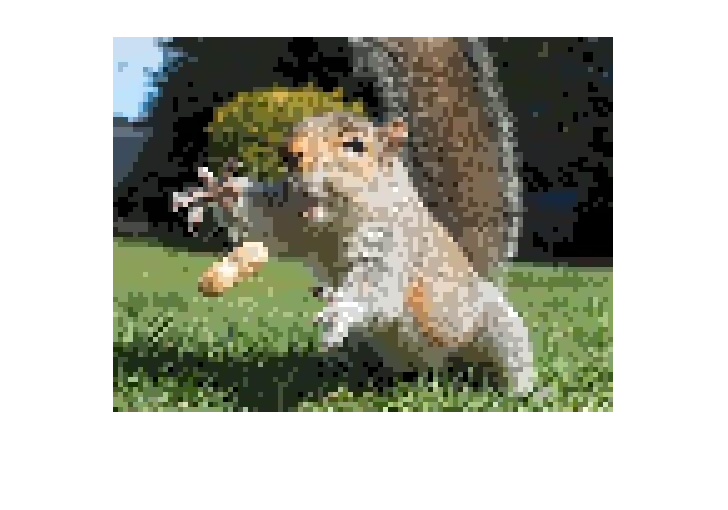

NTSCNewImage=NTSCImage;
NTSCNewImage(:,:,1) =double(OldImageGradient)/255;
NewColorImage =uint8(ntsc2rgb(NTSCNewImage)*255);
imshow(NewColorImage,'DisplayRange',[0 255]');

for i =1:3
    P(i) =corr2(NewColorImage(:,:,i),Image(:,:,i));
end
disp(P);

    0.9281    0.9245    0.9129



Повысить DPI после преобразований до 60.

Повысить корреляцию изображений до 0.98 в каждом канале.

Сколько бит информации весит изображение с такими условиями?

Во сколько раз отличается вес, исходного изображения и полученного (полутоннового)?

Для написания секции используйте код выше и help.

Оцените влияние метода интерполяции при изменении размера на коэффициенты корреляции.

Answer4 =0;
Answer5 =0;
Answer6 =0;
